Exercices en lien avec le cours de seance 5 et 7

Programme de l'algorithme des MC.

Sensibilisation aux structures de modèles (ARX, OE).

## I. Cas sans bruit

***Simulation des données non bruitées***

On simule dans un premier temps les données non bruitées qui nous serviront ensuite pour l'identification.

On simule : x=B/Au, x étant la sortie non bruitée

B=[0 0.2];
A=[1 -0.8];
N=200;

S=idpoly(1,B,1,1,A); %S=idpoly(A,B,1,A,1);
u=sign(randn(N,1));
x=sim(S,u);

Les données d'entrée/sortie non bruitées sont maintenant disponibles. 

***Estimation des paramètres à partir de u/x***

On écrit à la main l'estimateur des moindres carrés (MC)

Phi=[-x(1:N-1) u(1:N-1)];
Y=x(2:N);
theta_MC=(Phi\Y)'

theta_MC =    -0.8000    0.2000


L'estimation est parfaite car les données étant non bruitées; il s'agit de la résolution d'un système surdéterminé de N équations et 2 inconnues.

On peut faire de même avec les ***fonctions de Matlab***

datadet=iddata(x,u);    % objet données
nn=[1 1 1];             % nombre de paramètres à estimer
Marx=arx(datadet,nn);    % estimation par MC
present(Marx)

                                                                              
Marx =                                                                        
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                           
  A(z) = 1 - 0.8 (+/- 9.755e-18) z^-1                                         
                                                                              
  B(z) = 0.2 (+/- 3.019e-18) z^-1                                             
                                                                              
Sample time: 1 seconds                                                        
                                                                              
Parameterization:                                                             
   Polynomial orders:   na=1                                                  
   nb=1   nk=1                                                                
   Number of free coefficients: 2                   

Estimation parfaite également.

On peut aussi représenter à l'écran les données d'entrée/sortie

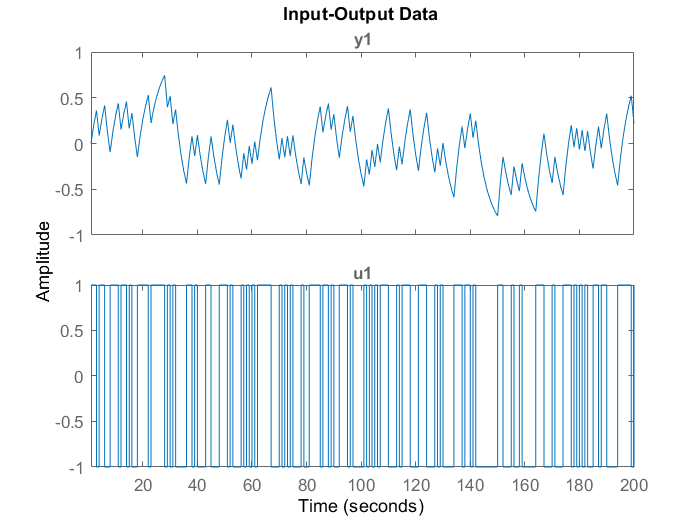

idplot(datadet)

## II. Cas bruité, Moindres Carrés

***Simulation des données bruitées (ARX)***

On simule dans un premier temps les données bruitées sous la forme d'un système ARX.

y=B/Au+1/Ae

nsr=0.2;    % noise_to_signal ratio
e=nsr*randn(N,1);
Sarx=idpoly(1,B,1,A,A); % Ay=B/F u+C/D e; idpoly(A,B,C,D,F)
yarx=sim(Sarx,[u e]);
dataSarx=iddata(yarx,u);

On peut représenter à l'écran les données d'entrée/sortie bruitées

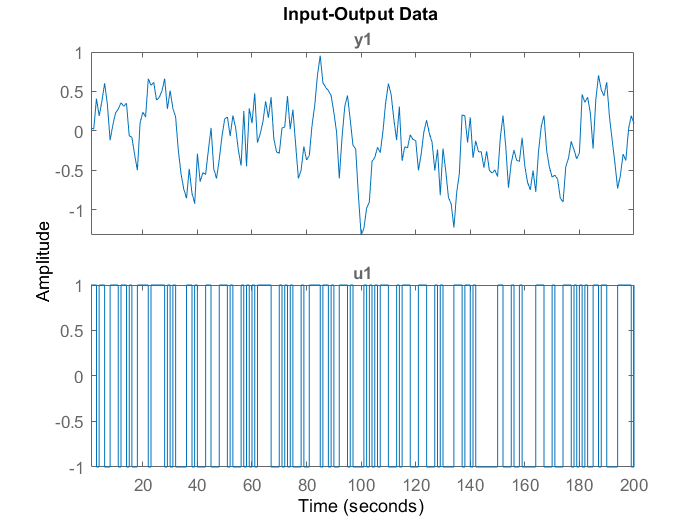

idplot(dataSarx)

***Estimation des paramètres à partir des données bruitées***

Phiarx=[-yarx(1:N-1) u(1:N-1)];
Yarx=yarx(2:N);
theta_MC_arx=(Phiarx\Yarx)'

theta_MC_arx =    -0.7723    0.2125


Avec la fonction de Matlab

Marx_arx=arx(dataSarx,nn);    % estimation par MC
present(Marx_arx)

                                                                              
Marx_arx =                                                                    
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                           
  A(z) = 1 - 0.7723 (+/- 0.03081) z^-1                                        
                                                                              
  B(z) = 0.2125 (+/- 0.01393) z^-1                                            
                                                                              
Sample time: 1 seconds                                                        
                                                                              
Parameterization:                                                             
   Polynomial orders:   na=1                                                  
   nb=1   nk=1                                                                
   Number of free coefficients: 2                   

On a généré des données avec un système de type ARX et on a estimé un modèle ARX (full order assumption), l'estimation est de bonne qualité.

Essayons maintenant de tester la robustesse de l'algorithme des MC sur le type de modèle. Ainsi, on va générer les données avec un système de type OE puis estimer un modèle ARX par MC.

***Simulation des données bruitées (OE)***

On simule dans un deuxième temps les données bruitées sous la forme d'un système OE.

y=B/Au+e

%nsr=0.2;
%e=nsr*randn(N,1);
Soe=idpoly(1,B,1,1,A);
yoe=sim(Soe,[u e]);
dataSoe=iddata(yoe,u);

***Estimation des paramètres à partir des données bruitées***

Phioe=[-yoe(1:N-1) u(1:N-1)];
Yoe=yoe(2:N);
theta_MC_oe=(Phioe\Yoe)'

theta_MC_oe =    -0.5293    0.2083


Avec la fonction de Matlab

Marx_oe=arx(dataSoe,nn);    % estimation par MC
%present(Marx_oe)

On a estimé un modèle de type ARX par l'estimateur des moindres carrés à partir de données ayant été générées par un système de type OE.

Les résultats sont de mauvaise qualité. L'estimateur ARX de donne pas satisfaction dans ce cas.

On peut remarquer que plus le niveau de bruit augmente, plus les résultats sont mauvais.

## III. Cas bruité, OE

On essaie ici d'utiliser OE pour Sarx et Soe.

Marx_oe=oe(dataSarx,nn);
Moe_oe=oe(dataSoe,nn);
present(Marx_oe)

                                                                              
Marx_oe =                                                                     
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                         
  B(z) = 0.2365 (+/- 0.02431) z^-1                                            
                                                                              
  F(z) = 1 - 0.7597 (+/- 0.05044) z^-1                                        
                                                                              
Sample time: 1 seconds                                                        
                                                                              
Parameterization:                                                             
   Polynomial orders:   nb=1                                                  
   nf=1   nk=1                                                                
   Number of free coefficients: 2                   

present(Moe_oe)

                                                                              
Moe_oe =                                                                      
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                         
  B(z) = 0.2114 (+/- 0.01133) z^-1                                            
                                                                              
  F(z) = 1 - 0.7768 (+/- 0.01656) z^-1                                        
                                                                              
Sample time: 1 seconds                                                        
                                                                              
Parameterization:                                                             
   Polynomial orders:   nb=1                                                  
   nf=1   nk=1                                                                
   Number of free coefficients: 2                   

## IV. Simulations de Monte Carlo

Matrice_param_arx_arx=[];
Matrice_param_arx_oe=[];
Matrice_param_oe_arx=[];
Matrice_param_oe_oe=[];

nsr=0.3;
MC=50;

for i=1:MC
    e=nsr*randn(N,1);
    yarx=sim(Sarx,[u e]);
    yoe=sim(Soe,[u e]);
    dataSarx=iddata(yarx,u);
    dataSoe=iddata(yoe,u);
    Marx_arx=arx(dataSarx,nn);
    Marx_oe=arx(dataSoe,nn);
    Moe_arx=oe(dataSarx,nn);
    Moe_oe=oe(dataSoe,nn);
    Matrice_param_arx_arx=[Matrice_param_arx_arx;[Marx_arx.B(2:end) Marx_arx.A(2:end)]];
    Matrice_param_arx_oe=[Matrice_param_arx_oe;[Marx_oe.B(2:end) Marx_oe.A(2:end)]];
    Matrice_param_oe_arx=[Matrice_param_oe_arx;[Moe_arx.B(2:end) Moe_arx.F(2:end)]];
    Matrice_param_oe_oe=[Matrice_param_oe_oe;[Moe_oe.B(2:end) Moe_oe.F(2:end)]];
end
%Valeur moyenne des paramètres estimés par MC (estimation du biais)
disp('Moyenne')

Moyenne


disp('SarxMarx_mc'),disp(mean(Matrice_param_arx_arx))

SarxMarx_mc
    0.1989   -0.7965



disp('SoeMarx_mc'),disp(mean(Matrice_param_arx_oe))

SoeMarx_mc
    0.2078   -0.4887



disp('SarxMoe_oe'),disp(mean(Matrice_param_oe_arx)) 

SarxMoe_oe
    0.1928   -0.7825



disp('SoeMoe_oe'), disp(mean(Matrice_param_oe_oe))

SoeMoe_oe
    0.1981   -0.8017




%ecart-type des paramètres estimés par MC (estimation de la dispersion
%autour de la valeur moyenne)
disp('ecart-type')

ecart-type


disp('SarxMarx_mc'),disp(std(Matrice_param_arx_arx))

SarxMarx_mc
    0.0205    0.0333



disp('SoeMarx_mc'),disp(std(Matrice_param_arx_oe))

SoeMarx_mc
    0.0246    0.0481



disp('SarxMoe_oe'),disp(std(Matrice_param_oe_arx)) 

SarxMoe_oe
    0.0340    0.0914



disp('SoeMoe_oe'), disp(std(Matrice_param_oe_oe))

SoeMoe_oe
    0.0155    0.0193



Ceci confirme la théorie : dans le cas d'une estimartion par MC, les résultats sont biaisés pour le cas où les données sont générées avec un système de type OE. Sinon, le MC donne de bons résultats (sans biais et variance minimale lorsque SARX et MARX).

Concernant l'estimateur OE, il donne des résultats précis (sans biais, fabile variance) lorsque le système et le modèle sont de type OE. En revanche, lorsque le système est de type ARX et le modèle de type OE, les résultats sont biaisés.

On remarque toutefois que les résultats obtenus par OE sont de meilleur qualité que ceux obtenus par ARX. Il faut faire très atttention à ne pas généraliser cette remarque qui ne s'applique qu'à notre système du 1er ordre choisi dès le départ.